# Lecture et stockage des données

clear variables;
close all;
clc;

globalParams.parametersCount = 4; % 3rd cell-array dimension

## Structure de stockage des données dans Matlab

Remise en forme par rapport aux fichiers des expériences successives.

Quatre dimensions pour l'expérience :

- i = Index d'expérience (du sujet d'expérience) [à partir de 1]

- j = Numéro de synthé [de 1 à 12, y compris les essais]. Complété par jbis = synthé via fader (indice{1}) ou via interpolation (indice{2})

- k = Numéro de paramètre [à partir de 1]

- Temps, de taille variable (et pour chaque valeur de temps, une valeur de paramètre)

Les 3 premières dimensions (y compris la 2bis qui n'est pas une dimension car taille fixe) sont stockées via un cell-array sur 4 indices qui a en fait la forme d'un pavé 3D.

La dernière dimension est stocké dans une matrice à 2 colonnes, de hauteur variable.

Nouvel indexage des expériences

Index +1 par rapport au C++ et aux noms des fichiers

Nouvel indexage des synthés

Qui doit commencer à partir de 1, car on ne va pas utiliser d'équivalent à std::map (qui permettaient de stocker les test dans des indices négatifs)

On décale de + le nombre de synthés de test (1 pour l'instant) puis +1 pour que les indices comment à zéro = +2 au total.

% fonction placees dans un sous-dossier
addpath('MatlabLib');

% 1 - - - Lecture du fichier d'infos - - -
% (pour connaitre le nombre d'experiences ?
% charger depuis les fichiers CSV et XML) general
xmlGeneralParams = xml2struct('A_OSC_Recorder_Experiment.xml');
% conversion vers des nombres pour tout ce qui est necessaire
globalParams.experimentsCount = str2num(xmlGeneralParams.experiments.count.Text); % dim 1
globalParams.synthsCount = str2num(xmlGeneralParams.experiments.synths.Attributes.total_count); % dim 2
globalParams.trialSynthsCount = str2num(xmlGeneralParams.experiments.synths.Attributes.trials_count);
% stockage des valeurs par d?faut dans un tableau.
% ligne = synth?, colonne = valeur du param par d?faut
globalParams.synthTargetValues = (-1) * ones(globalParams.synthsCount, globalParams.parametersCount);
for j = 1:globalParams.synthsCount
    % on suppose que les synth?s sont dans l'ordre dans le XML (pas de
    % v?rification de l'index)
    globalParams.synthNames{j,1} = xmlGeneralParams.experiments.synths.synth{1,j}.Attributes.name;
    % on suppose que les valeurs par d?faut des param?tres 
    % sont dans l'ordre !
    for k = 1:globalParams.parametersCount
        targetValue = str2double(xmlGeneralParams.experiments.synths.synth{1,j}.parameters.parameter{1,k}.Attributes.target_value);
        globalParams.synthTargetValues(j, k) = targetValue;
    end
end
clear xmlGeneralParams; clear targetValue

        % traduction ici du numero de synth
synthIdOffset = 1 + globalParams.trialSynthsCount;        

% 2 - - - Lecture des fichiers d'info XML de chaque experience - - -
for i = 1:globalParams.experimentsCount
    fileName = BuildInfoFileName(i-1);
    xmlExpeParams = xml2struct(fileName);
    experiments(i).presetsCount = str2num(xmlExpeParams.experiment.tested_presets.Attributes.count);
    % Ensuite on prevoit le stockage pour les experiences de tous les
    % synthes, avec ou sans faders. La moitie environ seulement sera utilise
    experiments(i).isSynthRecorded = false(globalParams.synthsCount, 2);
    experiments(i).synthIndexesInAppearanceOrder = -1000 * ones(globalParams.synthsCount, 1);
    % on regarde quelles synths ont vraiment ete testes par ce sujet
    % (les entrees invalides sont considerees comme non-enregistrees)
    for j=1:experiments(i).presetsCount
        synthIdx = synthIdOffset + str2num(xmlExpeParams.experiment.tested_presets.preset{1,j}.Attributes.synth_id);
        isValid = strcmpi(xmlExpeParams.experiment.tested_presets.preset{1,j}.Attributes.is_valid, 'true');
        if isValid        
            % interpolation ou faders ?
            isFromInterpolation = strcmpi(xmlExpeParams.experiment.tested_presets.preset{1,j}.Attributes.from_interpolation, 'true');
            if (isFromInterpolation)
                experiments(i).isSynthRecorded(synthIdx, 2) = true;
            else
                experiments(i).isSynthRecorded(synthIdx, 1) = true;
            end
            % ordre d'apparence ?
            appearanceIndex = str2num(xmlExpeParams.experiment.tested_presets.preset{1,j}.Attributes.appearance_index);
            % tous les essais sont ? 1
            if (appearanceIndex < 0)
                appearanceIndex = 1;
            % les autres sont ? partir de 2
            else
                appearanceIndex = appearanceIndex + 2;
            end
            experiments(i).synthIndexesInAppearanceOrder(appearanceIndex) = synthIdx;
        end
    end
end
clear synthIdx; clear isValid; % temp vars
clear isFromInterpolation; clear appearanceIndex;
clear xmlExpeParams;


% 3 - - - Lecture des CSV des mesures durant l'experience - - -
expeData = cell(globalParams.experimentsCount, globalParams.synthsCount, 2, globalParams.parametersCount);
for i = 1:globalParams.experimentsCount
    fileName = BuildDataFileName(i-1);
    csvData = dlmread(fileName, ';', 1, 0); % to skip the header
    lastSynthId = -1000; % pour d?clencher un nouveau synth
    lastFromInterp = -1000; % sera un bool?en
    lastParamId = -1000; % pour d?clencher un nouveau param?tre        
    % lecture du fichier par blocs, chaque bloc = 1 matrice de 2 colonnes
    curSubMatrixFirstRow = 1;
    for csvMatrixRow = 1:size(csvData, 1)
        curSynthId = csvData(csvMatrixRow, 1) + synthIdOffset;
        curFromInterp = csvData(csvMatrixRow, 2);
        curParamId = csvData(csvMatrixRow, 3);
        % d?tection d'un nouveau bloc d?s qu'une des 3 colonnes change
        if (curSynthId ~= lastSynthId) || (curFromInterp ~= lastFromInterp) || (curParamId ~= lastParamId)
            % copie de la matrice par extraction de sous-matrice
            % (si au moins une ligne ? copier...)
            if (csvMatrixRow > curSubMatrixFirstRow)
                % (attention : on s'arr?te au rang juste avant)
                if (lastFromInterp == 0)
                    expeData{i, lastSynthId, 1, lastParamId} = csvData( (curSubMatrixFirstRow:(csvMatrixRow-1)), [4 5]);
                else
                    expeData{i, lastSynthId, 2, lastParamId} = csvData( (curSubMatrixFirstRow:(csvMatrixRow-1)), [4 5]);    
                end
            end
            % et lancement d'un nouveau bloc dans tous les cas
            lastFromInterp = curFromInterp;
            lastSynthId = curSynthId;
            lastParamId = curParamId;
            curSubMatrixFirstRow = csvMatrixRow;
        else
            % sinon, on ne fait rien ! copie sera faite ? un moment...
        end
    end
    % ? la fin, on sauvegarde le dernier bloc (qui ?tait en cours)
    % (attention : on s'arr?te au rang courant, de sortie de boucle)
    if (lastFromInterp == 0)
        expeData{i, lastSynthId, 1, lastParamId} = csvData( (curSubMatrixFirstRow:(csvMatrixRow)), [4 5]);
    else
        expeData{i, lastSynthId, 2, lastParamId} = csvData( (curSubMatrixFirstRow:(csvMatrixRow)), [4 5]);    
    end
end

clear i; clear j; clear j; clear k;
clear csvData; clear csvMatrixRow; clear fileName;
clear curSynthId; clear curFromInterp; clear curParamId;
clear lastSynthId; clear lastFromInterp; clear lastParamId;
clear curSubMatrixFirstRow;

# Pré-traitement des données

- Redimensionnements des vecteurs temps

- Conversion des unités (temps millisecondes -> secondes)

- Recentrage des valeurs de paramètres autour de zéro (translation de "- objectif"). Les graphes seront donc directement une visualisation de l'erreur

% "Fermeture" des courbes : ajout de points en zéro et pour le dernier
% temps mesuré (pour tous les paramètres)
for i1 = 1:globalParams.experimentsCount
    for j = 1:globalParams.synthsCount
        for jbis = 1:2
            % passe 1 : mesure du temps max, pour n'importe quel paramètre
            lastTime = -1.0;
            for k = 1:globalParams.parametersCount
                if ( ~ isempty(expeData{i1, j, jbis, k}) )
                    % dernière ligne, première colonne
                    if (expeData{i1, j, jbis, k}(end, 1) > lastTime)
                        lastTime = expeData{i1, j, jbis, k}(end, 1);
                    end
                % - - - sécurité : si manque un paramètre, test du synthé est invalidé - - -
                else
                    experiments(i1).isSynthRecorded(j,jbis) = false;
                end
            end
            % passe 2 : application des extensions des graphes en zéro et à la fin
            if (experiments(i1).isSynthRecorded(j,jbis))
                for k = 1:globalParams.parametersCount
                    expeData{i1, j, jbis, k} = ExtendFirstAndLastValues(expeData{i1, j, jbis, k}, lastTime);
                end
            end
        end
    end
end

% Conversion millisecondes -> secondes pour le temps
for i1 = 1:globalParams.experimentsCount
    for j = 1:globalParams.synthsCount
        for jbis = 1:2
            for k = 1:globalParams.parametersCount
                if ( ~ isempty(expeData{i1, j, jbis, k}) )
                    rowsCount = size(expeData{i1, j, jbis, k}, 1);
                    conversionMatrix = [ (ones(rowsCount, 1)*0.001) ones(rowsCount, 1) ];
                    % produit de Hadamard (multiplication terme à terme)
                    expeData{i1, j, jbis, k} = conversionMatrix .* expeData{i1, j, jbis, k};
                end
            end
        end
    end
end

% Recentrage des valeurs des paramètres autour de zéro 
for i1 = 1:globalParams.experimentsCount
    for j = 1:globalParams.synthsCount
        for jbis = 1:2
            for k = 1:globalParams.parametersCount
                if ( ~ isempty(expeData{i1, j, jbis, k}) )
                    rowsCount = size(expeData{i1, j, jbis, k}, 1);
                    centeringMatrix = [ zeros(rowsCount, 1) (-1 * ones(rowsCount, 1) * globalParams.synthTargetValues(j, k)) ];
                    % produit de Hadamard (multiplication terme à terme)
                    expeData{i1, j, jbis, k} = centeringMatrix + expeData{i1, j, jbis, k};
                end
            end
        end
    end
end

clear parameterCurve; clear rowsCount; clear conversionMatrix; clear centeringMatrix; clear lastTime;
clear i1; clear j; clear jbis; clear k;


# Calcul des indices de performance

Notations :

- $i$ est un numéro d'expérience

- $j$ est un numéro de synthé

- $F|I$ peut être soit F=Fader (jbis=1 dans le code) soit I=Interpolation (jbis=2 dans le code). Toutes les grandeurs ci-dessous peuvent être soit F soit I

- $k \in [1;n]$ est un numéro de variable dans un état

- $N_E$ = nombres d'Expériences menées = nombre de sujets d'Expérience

- $N_S$ = nombre de Synthétiseurs testés = 10 mesurés + 1 de test au départ

- $X_{i,j}(t) = \left( \begin{array}{c}
x_1 \\
\vdots \\
x_n
\end{array} \right)_{i,j}(t)$ = l'État des paramètres à un instant $t$ 

- n = 4 = nombre de variables (= paramètres contrôlables) pour chaque synthétiseur.

Pour chaque expé $i$, pour chaque synthé testé $j$ :

- $$T(i,j)$$ = Durée totale de la recherche des paramètres du preset (en secondes).

- $E(i,j)$ = Erreur moyenne (et donc déjà normalisée) à la fin de la recherche. En fait, calculée à partir de la norme 1 du vecteur-état : $E(i,j) = \frac{  \left\vert \left\vert X_{i,j}(T(i,j)) \right\vert \right\vert_1  }   {n} > 0$ 

- $P(i,j)$ = Indice de performance de précision en % / seconde. $P(i,j) = \frac{1-E(i,j)}{T(i,j)}$. ***Ce calcul devra certainement être modulé, par exemple en considérant le temps comme moins pénalisant... ?*** Comme avec $P(i,j) = \frac{1-E(i,j)}{ln(1 + T(i,j))}$ par exemple

% 1ière passe : valeurs par graphe
for i1 = 1:globalParams.experimentsCount
    for j = 1:globalParams.synthsCount
        for jbis = 1:2
            if (experiments(i1).isSynthRecorded(j, jbis)) 
                expeResults(i1).T(j, jbis) = expeData{i1, j, jbis, 1}(end,1); % premier paramètre seulement
                expeResults(i1).E(j, jbis) = 0.0;
                for k = 1:globalParams.parametersCount % ajout de la norme 1 du vecteur (mais impossible d'extraire le vecteur facilement...)
                    expeResults(i1).E(j, jbis) = expeResults(i1).E(j, jbis) + abs(expeData{i1, j, jbis, k}(end,2));
                end
                expeResults(i1).E(j, jbis) = expeResults(i1).E(j, jbis) / globalParams.parametersCount;
                % =======================================================
                % =======================================================
                % FORMULE DE L'INDICE DE PERFORMANCE DÉFINIE ICI
                %expeResults(i1).T_dist(j, jbis) = log( 1 + expeResults(i1).T(j, jbis) );
                expeResults(i1).T_dist(j, jbis) = expeResults(i1).T(j, jbis);
                expeResults(i1).P(j, jbis) = (1.0 - expeResults(i1).E(j, jbis)) / expeResults(i1).T_dist(j, jbis);
                % =======================================================
                % =======================================================
            else
                expeResults(i1).T(j, jbis) = -1.0;
                expeResults(i1).T_dist(j, jbis) = -1.0;
                expeResults(i1).E(j, jbis) = -1.0;
                expeResults(i1).P(j, jbis) = -1.0;
            end
        end
    end
end
clear i1; clear j; clear jbis; clear k;

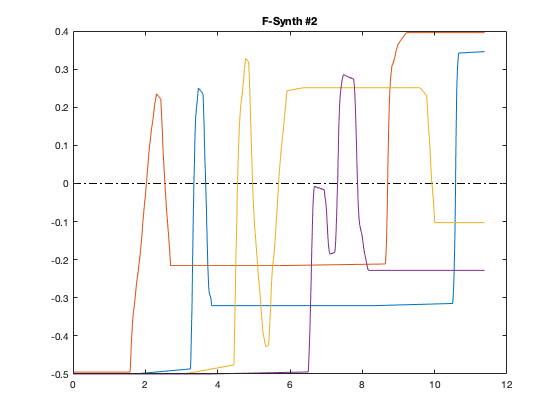

% Affichage d'une expérience en particulier :
expeToDisplay =  2;
%                                        Numéro de graphe (0 : tous les graphes)
DisplayCurves(globalParams, experiments, expeData, expeToDisplay,2);

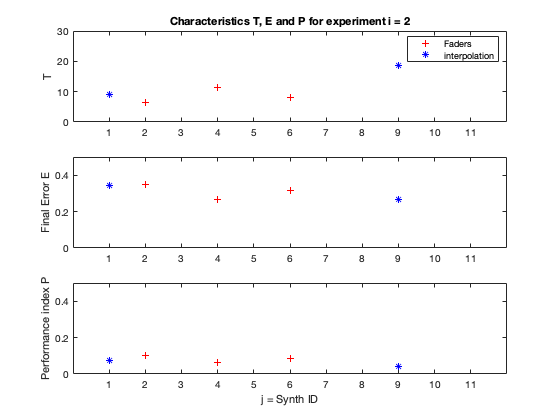


% Visualisation des erreurs, temps et performance (par expérience, pour chaque synthé)
DisplayExpeResults(globalParams, expeResults, expeToDisplay);

clear expeToDisplay;

# Tentatives d'extraction de caractéristiques, à partir des indices de performance

Pour chaque synthé (dans synthResults)

- $\overline{P(j)}= \frac{ \sum\limits_{i=1}^{N_E}  { P(i,j) }} {N_E}$ Indice de performance moyen (moyenne sur toutes les expériences i).* Objectif : pouvoir comparer l'indice de performance avec faders ou avec MIEM*

Pour chaque expé, pour chaque synthé :

- $\Delta P(i,j) =  P(i,j) - \overline{P(j)}$ = Variation d'indice de performance, par rapport à la moyenne de performance pour ce synthé. *Objectif : pour faire le calcul de la variation de performance d'un utilisateur, par rapport à une moyenne*

Pour chaque expé : 

- $\overline{\Delta P(i) } = \frac{ \sum_j{\Delta P(i,j)} }{N_S}$  = Moyenne (sur tous les synthés) de la variation d'indice de performance. *Objectif : savoir si l'interface apporte quelque chose aux utilisateurs novices, car chaque utilisateur estime sur une échelle de un à cinq son propre degré d'expertise dans le contrôle des sons et effets de synthétiseurs*


% 2nde  passe : les MOYENNES I(j) sur toutes les expériences i
for j = 1:globalParams.synthsCount
    for jbis = 1:2
        synthResults(j).mean_P(jbis) = -1.0;
        currentPCount = 0;
        for i1 = 1:globalParams.experimentsCount
            if (expeResults(i1).P(j, jbis) >= 0.0)
                currentPCount = currentPCount + 1;
                currentP(currentPCount) = expeResults(i1).P(j, jbis); % taille dynamique
            end
        end
        if (currentPCount >= 1)
            synthResults(j).mean_P(jbis) = mean(currentP);
        end
    end
end



% 3ème  passe : valeurs moyennes de performance pour chaque sujet d'expérience


clear i1; clear j; clear jbis; clear k;